# Three-Phase Photovoltaic (PV) System

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

A three-phase solar grid system converts DC power from solar panels into three-phase AC power so it can be transmitted efficiently and delivered to grid-connected loads.

A three-phase inverter synchronizes the generated AC power with the grid frequency and phase. Control techniques such as proportional-integral (PI) control and maximum power point tracking (MPPT) allow the system to respond to irradiance and temperature changes while maintaining stable grid operation.

By the end of this activity, you should be able to explain how PV array behavior, MPPT, inverter control, and grid synchronization work together in a three-phase grid-connected PV system.

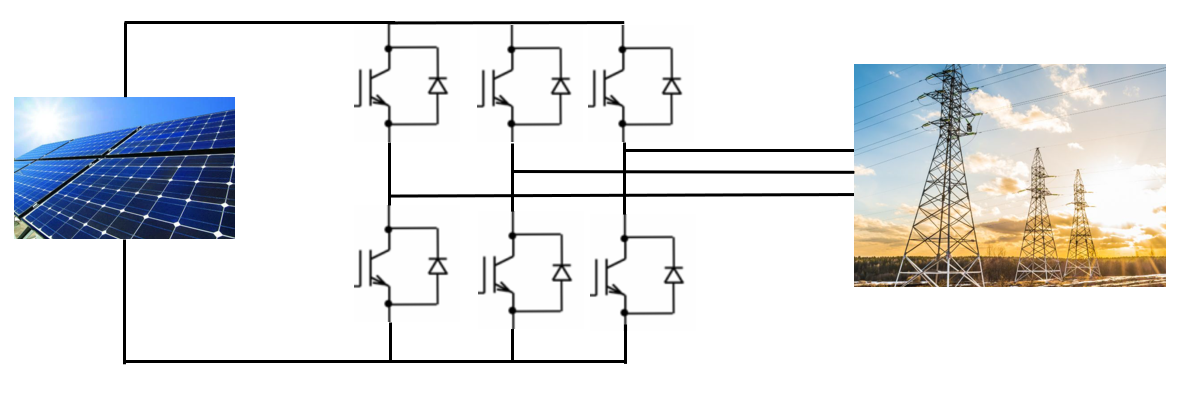

The structure of the three-phase PV system 

## 2. Circuit

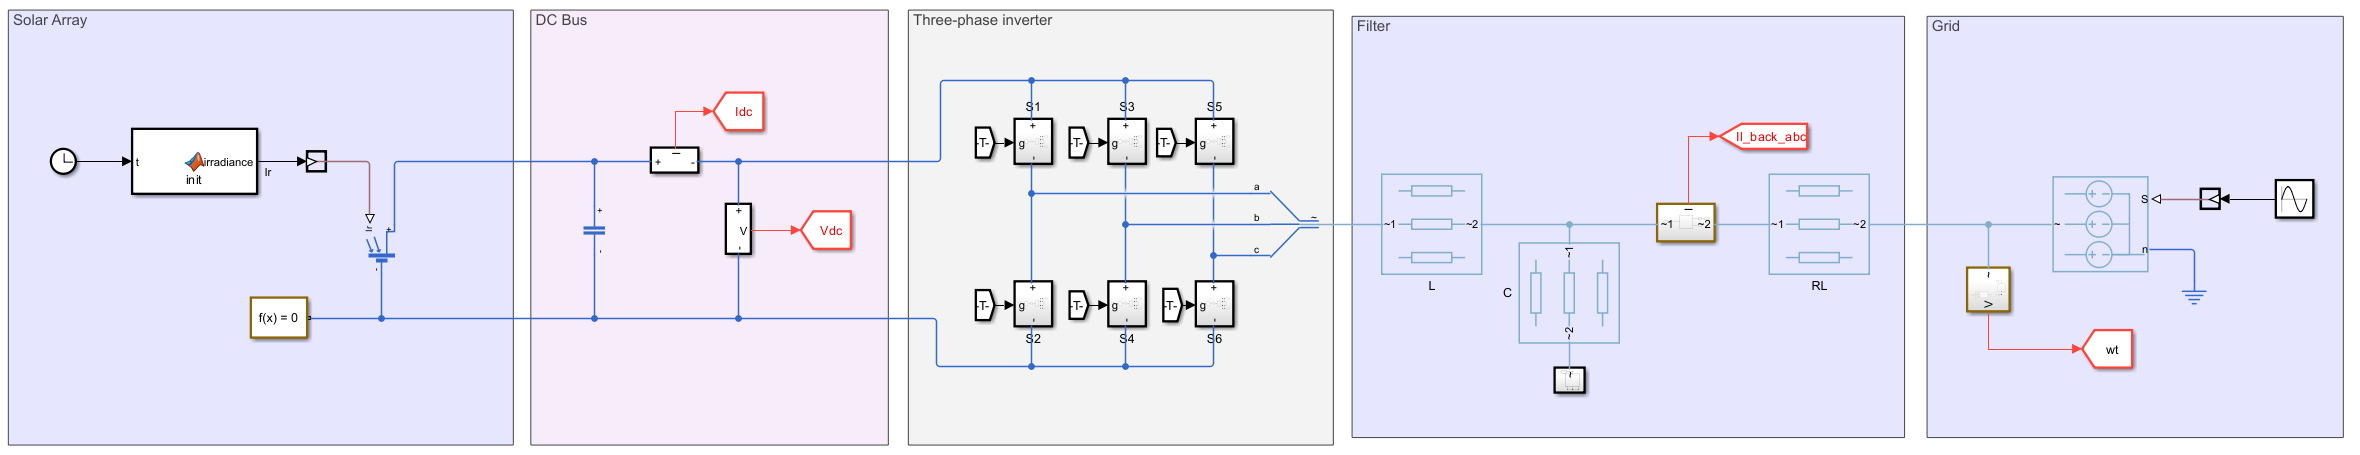

The circuit above shows the solar array connected to the power grid through a three-phase inverter and a filter. 

Click the button below to learn more about different sections of the model: 

selection1 = "No Selection";
switchRectifier(selection1);

### 2.1 Solar Panel

Photovoltaic (PV) technology converts solar irradiance into electrical power using semiconductor materials. In this section, connect the physical PV module to the I-V and P-V curves that determine how much power the system can extract.

The image below shows a real PV module.

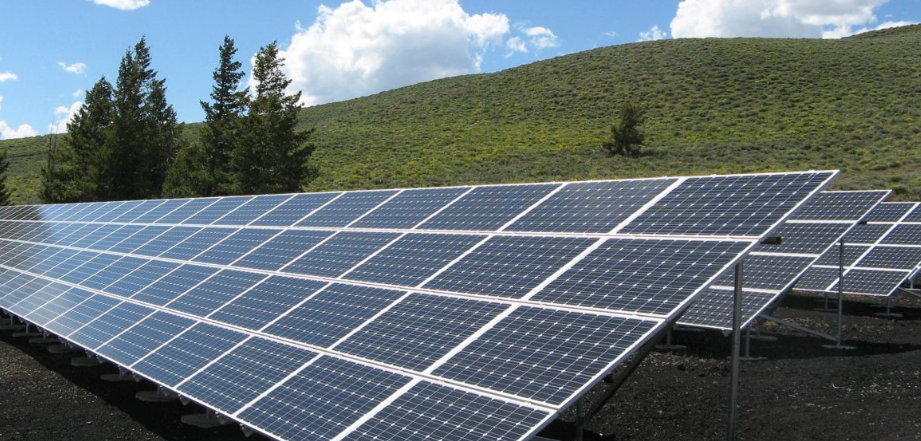

**I-V curves show the relationship between current and voltage under specified irradiance and temperature conditions, commonly 1000 **$\bm{w}/{\bm{m}}^2$** and 25 degrees Celsius.**

The following Simulink model shows the detailed structure of the PV model:

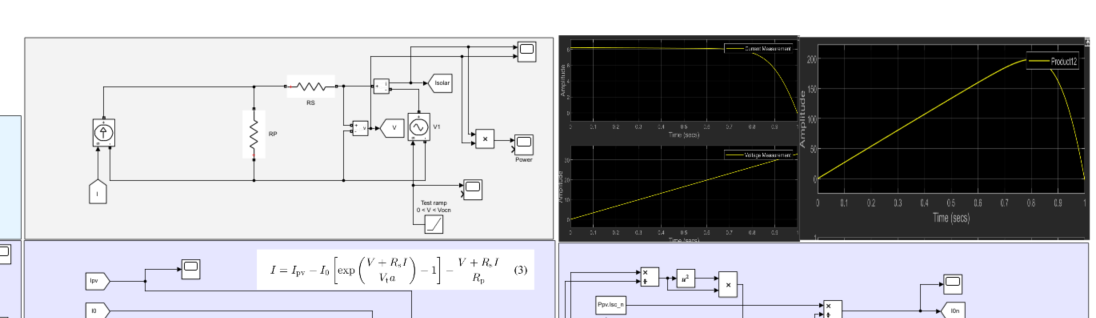

Open the detailed PV model and identify where irradiance and temperature enter the model.

 
open_system("Models/ThreePhasePVModule.slx")

Before moving the sliders, predict how lower irradiance or higher temperature will affect the I-V and P-V curves. Then adjust the irradiance and temperature and compare the plots with your prediction.

Irradiance=688;
Temperature=37;
 
pv_curves(Irradiance, Temperature);

### 2.2 Three-Phase PV Circuit Simulation

Let's turn our attention back to the full PV circuit.

Before running, predict which signals should settle and which should track changing operating conditions. Then click Open & Run and inspect the model behavior.

After the simulation is complete (allow a few minutes), use the following plots to connect the circuit behavior with the controller objectives:

- DC Bus Voltage

- Inverter Output Current 

- Output Active Power

- MPPT Voltage (Vmppt)

disp("Please wait for the simulation to finish. This may take a few minutes")
run('Initialization_PV.m')
open_system('Models/three_phase_solar_grid_SSC.slx')
warning('off','all')
simOut = sim('Models/three_phase_solar_grid_SSC.slx', 'ReturnWorkspaceOutputs', 'on');
runmodel_threephase(simOut);
disp("Simulation completed. You can now analyze the results")

### 2.3 Three-Phase Inverter

A three-phase inverter converts DC power into three-phase AC power. In this model, it is the interface between the PV system and the grid, so its switching and control behavior determine the quality of the output current.

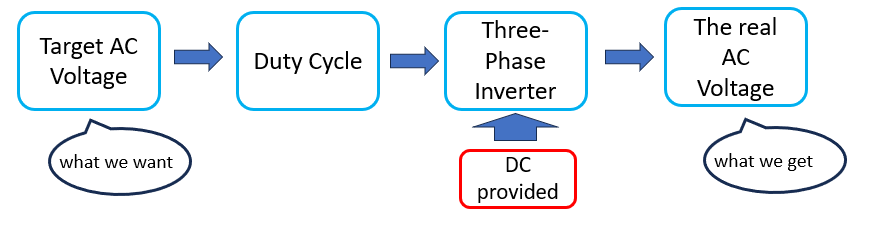

### 2.4 Grid Connection

For this simulation, the inverter output must match the grid frequency and phase angle. A phase-locked loop (PLL) estimates the grid phase and frequency. You do not need to analyze the PLL internals here; focus on how synchronization supports grid connection.

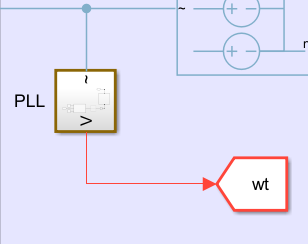

## 3. Control Algorithm

The control algorithm combines maximum power point tracking (MPPT) with inverter control.

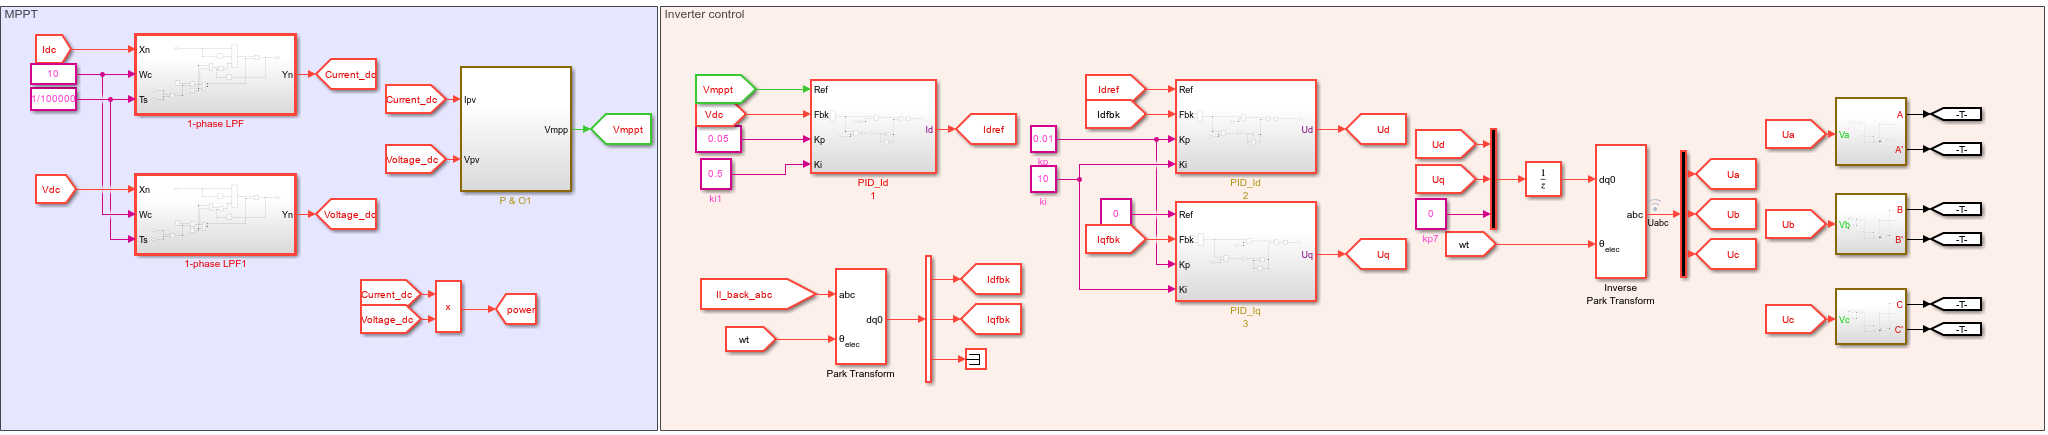

### 3.1 Maximum Power Point Tracking (MPPT)

MPPT control adjusts the PV operating point so the array stays near the maximum of the power-voltage curve. This point is called the maximum power point (MPP), and it changes when irradiance or temperature changes.

Two common MPPT methods are perturbation and observation (P&O) and incremental conductance. This model uses the P&O method.[](https://www.mathworks.com/discovery/mppt-algorithm.html)

MPPT("No Selection")

As you run the model, watch whether Vmppt tracks the operating point selected by the MPPT controller.

### 3.2 Inverter Control

The inverter control combines current control, voltage control, and duty-cycle generation.

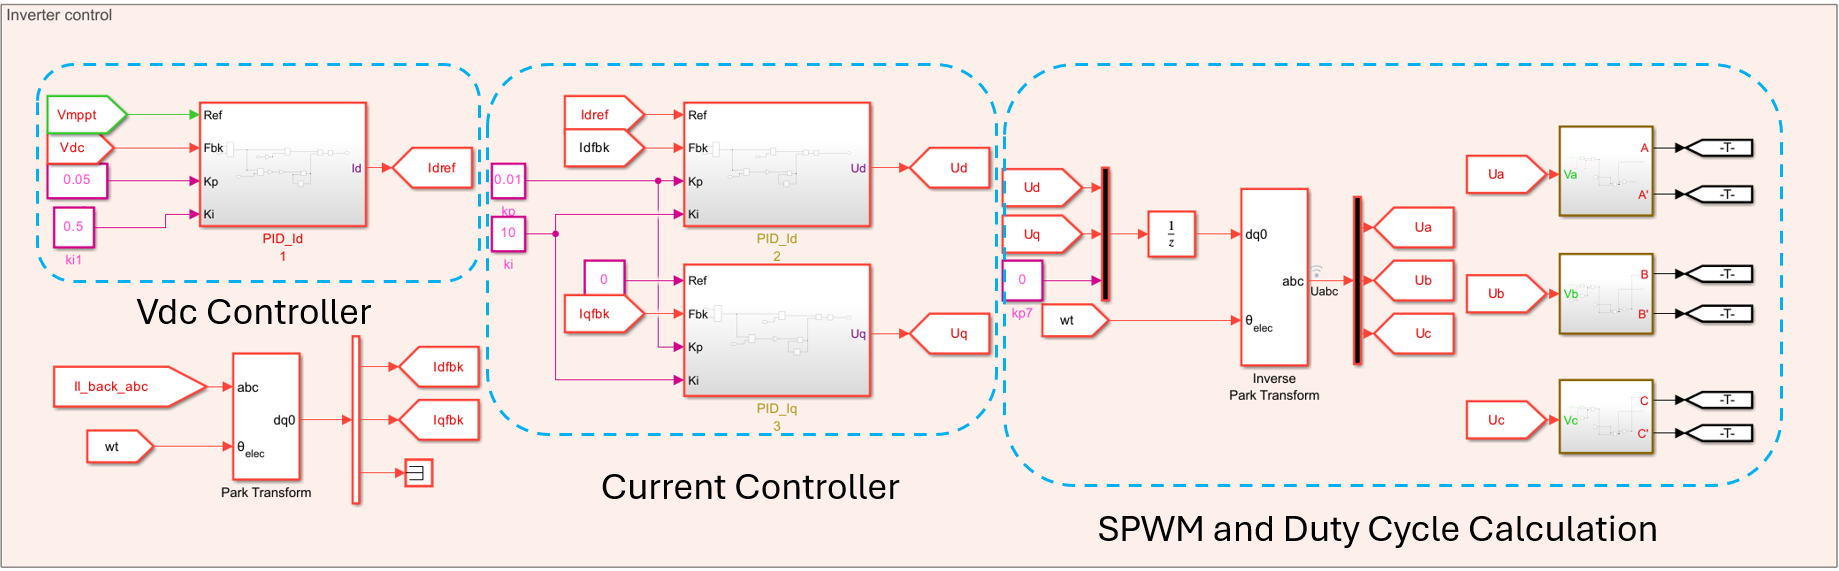

**Reflection**

- Why do we need **current** and **voltage** controllers? Or, put another way, why do we need to control **current **and **voltage?**

- How does the algorithm generate the duty cycle through sinusoidal pulse-width modulation?

Use the drop-down menu to inspect each controller and connect it to the signals you observed in simulation.

controller("No Selection")

## 4. Analyzing model results

Run the three-phase solar model. Once the simulation is complete (allow a few minutes), use the scopes to evaluate whether the controller met its objectives.

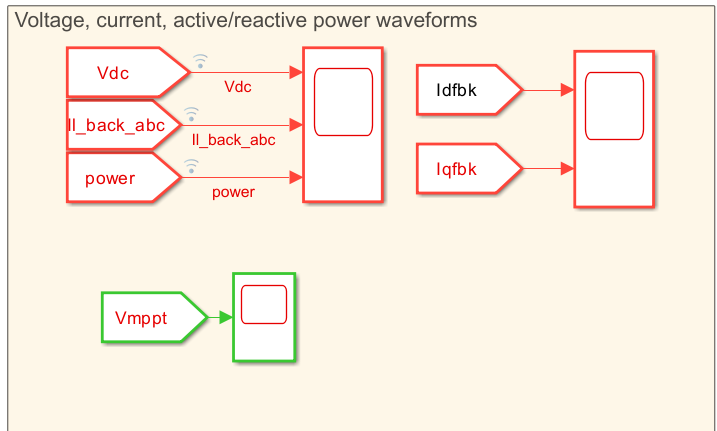

Use the plots to answer these questions:

- Is Vdc stable at the maximum power point (MPP)?

- Is the three-phase current a smooth sine wave?

If the simulation results satisfy the above conditions, Id, Iq, and Vmppt are stable. This means the control algorithm is doing its job.  

Use the menu below to compare your results with the reference simulation results.

result("No Selection")

## 5. Conclusion

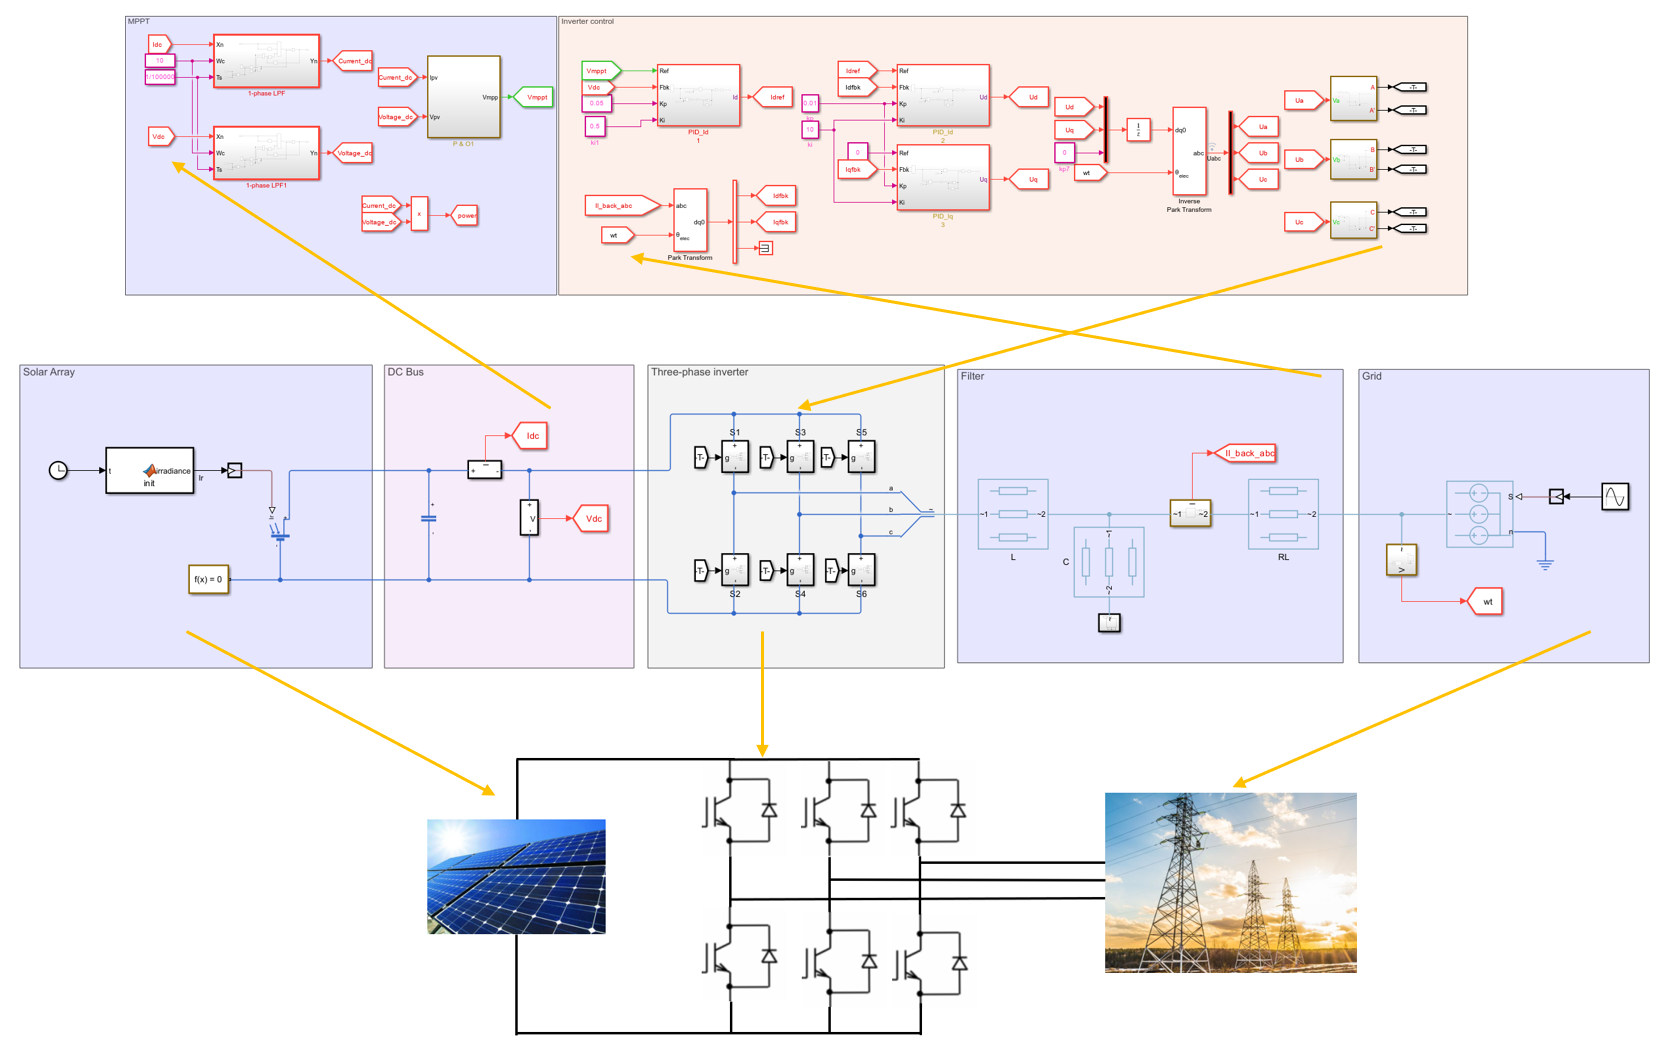

The Three-Phase PV System presented in this simulation provides a comprehensive overview of solar power generation, conversion, and integration into the electrical grid. Through the combined operation of the PV panel, MPPT controller, inverter, and grid connection, the system effectively demonstrates how renewable energy can be reliably harnessed and synchronized with utility power standards.

The MPPT algorithm ensures that the solar panels operate at their optimal power point under varying irradiance and temperature conditions. The inverter control structure, including both voltage and current control loops, maintains grid synchronization and ensures efficient power conversion from DC to three-phase AC. Simulation results confirm the system’s ability to stabilize the DC bus voltage, track MPPT reference voltage, and generate smooth sinusoidal three-phase currents.

After completing this activity, you should be able to explain how changes in irradiance and temperature affect PV output, how MPPT responds, and how inverter control supports grid-connected three-phase power delivery.

## 6. Exercises

**Exercise 1. Which current component in the inverter control represents active power transfer?**

exerciseSol1(...
     false, ...
   false);
 

**Exercise 2. In P&O MPPT control, if the current power is higher than the previous power but the current voltage is lower than the previous voltage, what will the MPPT algorithm do with the Vmppt output? Explain your reasoning.**

exerciseSol2(...
     false, ...
   false);
 

**Exercise 3. In the three-phase model, find the MOSFET switching frequency. Hint: Check the duty-cycle generation block, then explain how the switching frequency relates to the inverter output waveform.**

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Solar Panel" "Three-Phase inverter" "Grid"])}
end
clf;
if opt == "No Selection"
else
   if opt == "Solar Panel"
     rect = imread("Images/ThreePhasePV/PV.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "Three-Phase inverter"
        rect = imread("Images/ThreePhasePV/inverter.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "Grid"
        rect = imread("Images/ThreePhasePV/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    end
end
end

function MPPT(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "P&O" "Incremental Conductance"])}
end
clf;
if opt == "No Selection"
else
    if opt == "P&O"
        rect = imread("Images/ThreePhasePV/PO.jpg");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Incremental Conductance"
        rect = imread("Images/ThreePhasePV/IC.jpg");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Controllers" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Controllers"
        rect = imread("Images/ThreePhasePV/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/ThreePhasePV/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Circuit Part" "Control Part"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Circuit Part"
        rect = imread("Images/ThreePhasePV/circuitpart.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Control Part"
        rect = imread("Images/ThreePhasePV/controlpart.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end


function pv_curves(Irradiance, Temperature)
    V = linspace(0, 32.9, 100);  
    T = Temperature + 273;  
    G = Irradiance;
    k = 1.38064852e-23;
    q = 1.602176634e-19;
    Ns = 54;
    Voc_n = 32.9;
    Isc_n = 8.21;
    Rs = 0.2210;
    Rp = 415.405;
    a = 1.3;
    Eg = 1.12;
    KI = 0.0032;
    Ipv_n = 8.21;
    G_n = 1000;
    T_n = 298;
    Vt = Ns * k * T / q;
    
    I0 = calculate_saturation_current(T, T_n, Isc_n, Voc_n, Eg, a);
    Ipv = calculate_pv_current(Ipv_n, KI, (T - T_n), G, G_n);
    
 
    I_values = arrayfun(@(v) calculate_current(Ipv, I0, Rs, Rp, v, Vt, a), V);
    
  
    P = V .* I_values;
    
    figure('Position', [100, 100, 1200, 400]);  
    subplot(1, 2, 1); 
    plot(V, I_values, 'b', 'LineWidth', 2); 
    title('I-V Curve');
    xlabel('Voltage (V)');
    ylabel('Current (A)');
    grid on;
    ylim([0 10]);
 
    
    subplot(1, 2, 2);  
    plot(V, P, 'r', 'LineWidth', 2);  
    title('P-V Curve');
    xlabel('Voltage (V)');
    ylabel('Power (W)');
    grid on;
    ylim([0 220]);
   

end

function I0 = calculate_saturation_current(T, Tn, Iscn, Vocn, Eg, a)
    k = 1.38064852e-23;  
    q = 1.602176634e-19;  
  
    Vt_n = 54*k * Tn / q;  
    I0n = Iscn / (exp(Vocn / (a * Vt_n)) - 1);
    
    I0 = I0n * (Tn / T)^3 * exp(q * Eg / (a * k) * (1 / Tn - 1 / T));
end

function Ipv = calculate_pv_current(Ipv_n, KI, DeltaT, G, Gn)
    Ipv = (Ipv_n + KI * DeltaT) * (G / Gn);
end


function I = calculate_current(Ipv, Io, Rs, Rp, V, Vt, a)
    options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);
    f = @(I) Ipv - Io * (exp((V + Rs * I) / (Vt * a)) - 1) - (V + Rs * I) / Rp - I;
    I = fzero(f, Ipv, options);
end

function exerciseSol1(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select an answer!")
    elseif A && B
        disp("Please select only one answer")
    elseif A
        disp("Correct!")
    else 
        disp("Incorrect. please review the inverter control section.")
    end
end

function exerciseSol2(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select an answer!")
    elseif A && B
        disp("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        disp("Incorrect. Please review the MPPT section.")
    end
end
function exerciseSol3(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif sum([A B C]) > 1 
        disp("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        disp("Incorrect. I know this is hard but try to dive deeper.")
    end
end

function runmodel_threephase(simOut)

try

    Vdc_struct         = simOut.get('Vdc');
    Il_back_abc_struct = simOut.get('Il_back_abc');
    power_struct       = simOut.get('power');
    Vmppt_struct       = simOut.get('Vmppt');

    [t1, Vdc]         = extractSignal(Vdc_struct);
    [t2, Il_back_abc] = extractSignal(Il_back_abc_struct);
    [t3, power]       = extractSignal(power_struct);
    [t4, Vmppt]       = extractSignal(Vmppt_struct);

    Vdc_plot = squeeze(Vdc);
    power_plot = squeeze(power);
    Vmppt_plot = squeeze(Vmppt);

    Il_back_abc_plot = squeeze(Il_back_abc);

    if ndims(Il_back_abc_plot) > 2
        Il_back_abc_plot = Il_back_abc_plot(:,:,1); 
        disp('⚠️ Warning: Il_back_abc was 3D. Plotting only the first "page" (Il_back_abc(:,:,1)).');
    elseif size(Il_back_abc_plot, 1) < size(Il_back_abc_plot, 2)
        Il_back_abc_plot = Il_back_abc_plot.';
    end

    figure('Name','Three-Phase PV Results','NumberTitle','off','Position',[100,100,1200,800]);

    subplot(2,2,1);
    plot(t1, Vdc_plot, 'LineWidth', 1.5);
    title('DC Bus Voltage (Vdc)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Voltage (V)','FontSize',10); grid on;

    subplot(2,2,2);
    plot(t2, Il_back_abc_plot, 'LineWidth', 1.5);
    title('Inverter Output Current (Il\_back\_abc)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Current (A)','FontSize',10); grid on;
    legend('Phase A', 'Phase B', 'Phase C', 'Location', 'best');


    subplot(2,2,3);
    plot(t3, power_plot, 'LineWidth', 1.5);
    title('Output Active Power','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Power (W)','FontSize',10); grid on;

    subplot(2,2,4);
    plot(t4, Vmppt_plot, 'LineWidth', 1.5);
    title('MPPT Voltage (Vmppt)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Voltage (V)','FontSize',10); grid on;


catch ME
    disp('❌ Error occurred during plotting:');
    disp(ME.message);
    disp('---');
    disp('**DEBUGGING TIP:** The error is likely due to the dimensionality of the data.');
    disp('Check the size of your signals in the Command Window (e.g., size(simOut.get(''Il_back_abc'').signals.values))');
end
end

function [time, values] = extractSignal(sigStruct)
    if isstruct(sigStruct) && isfield(sigStruct, 'time') && isfield(sigStruct, 'signals')
        time = sigStruct.time;
        values = sigStruct.signals.values;
    else
        time = []; values = [];
        warning('⚠ Unexpected signal format.');
    end
end